originFile = "./data/type2/18/1_44k_2k_8k_100_pure.wav";
recordFile = "./data/type2/18/record.wav";
lowerLimit = 2000

lowerLimit =         2000


upperLimit = 8000

upperLimit =         8000


outputFigPath = "./data/type2/18/";
samplingRate = 44100

samplingRate =        44100


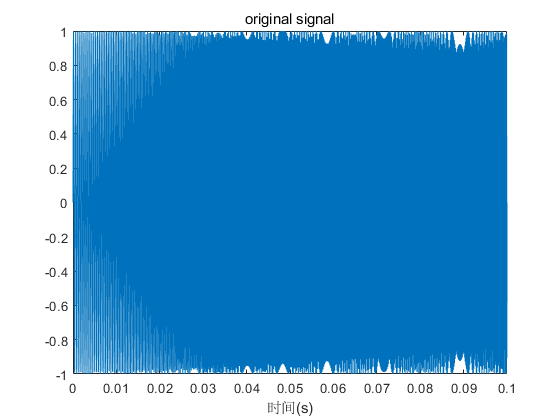

[originY, originFs] = audioread(originFile);
originT = (0:length(originY)-1)/originFs;
originLen = length(originY);
fig = figure;
plot(originT, originY)
title("original signal")
xlabel("时间(s)");
saveas(fig, strcat(outputFigPath, "original_signal.png"))


[recordY, recordFs] = audioread(recordFile);
recordY = recordY(floor(0.2 * samplingRate):length(recordY))

recordY =   -0.005157470703125
  -0.005004882812500
  -0.004882812500000
  -0.004760742187500
  -0.004760742187500
  -0.004882812500000
  -0.004699707031250
  -0.004638671875000
  -0.004425048828125
  -0.004364013671875


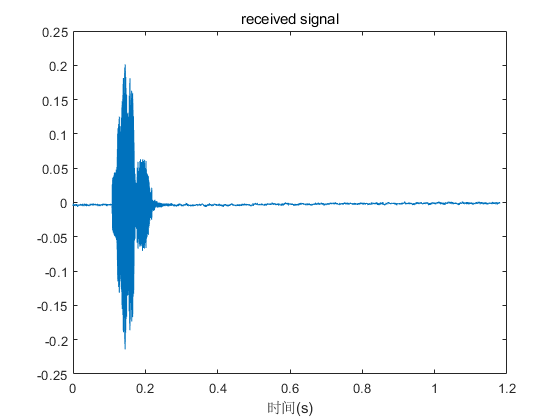

recordT = (0:length(recordY)-1)/recordFs;
recordLen = length(recordY);
fig = figure;
plot(recordT, recordY)
title("received signal")
xlabel("时间(s)");
saveas(fig, strcat(outputFigPath, "received_signal.png"))

## 频域处理

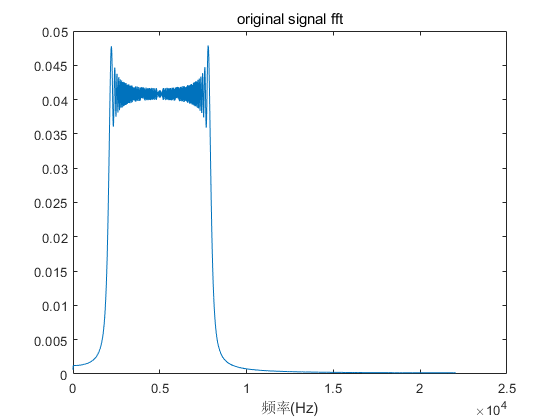

% fft
originFftY = abs(fft(originY)) / (originLen / 2);
originFftY(1) = originFftY(1) / 2;
f = originFs * (0:originLen - 1) / originLen;
fig = figure;
plot(f(1:ceil(originLen/2)), originFftY(1:ceil(originLen/2)));
title("original signal fft")
xlabel("频率(Hz)");
saveas(fig,strcat(outputFigPath, "original_signal_fft.png"));

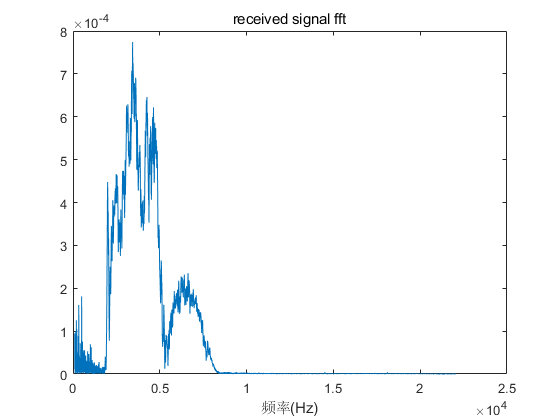



%% 频域处理
recordfftY = abs(fft(recordY)) / (recordLen / 2);
recordfftY(1) = recordfftY(1) / 2;
f = recordFs * (0:recordLen - 1) / recordLen;
fig = figure;
plot(f(ceil(100*recordLen/samplingRate):ceil(recordLen/2)), recordfftY(ceil(100*recordLen/samplingRate):ceil(recordLen/2)));
title("received signal fft")
xlabel("频率(Hz)");
saveas(fig,strcat(outputFigPath, "received_signal_fft.png"));

## 频谱图

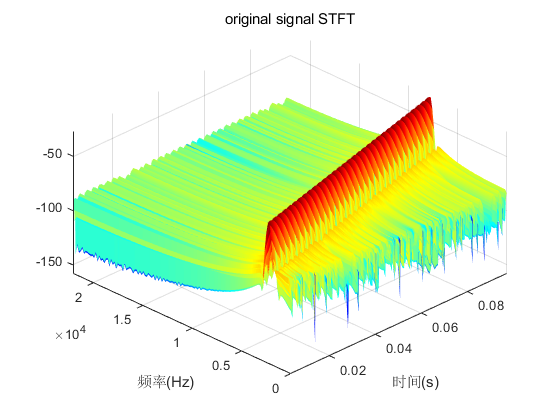

fig = figure;
[y,f,t,p] = spectrogram(originY, 256, 250, 256, samplingRate);
surf(t,f,10*log10(abs(p)),'EdgeColor','none');  
axis xy; axis tight; colormap(jet); 
view(-45,45);
xlabel('时间(s)');
ylabel('频率(Hz)');
title("original signal STFT");

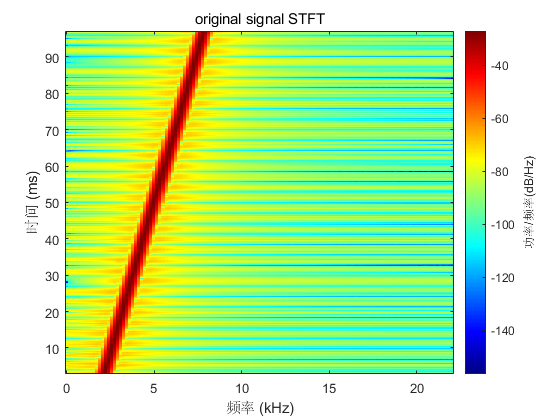

spectrogram(originY, 256, 250, 256, samplingRate);
title("original signal STFT");
saveas(fig,strcat(outputFigPath, "original_signal_STFT.png"));

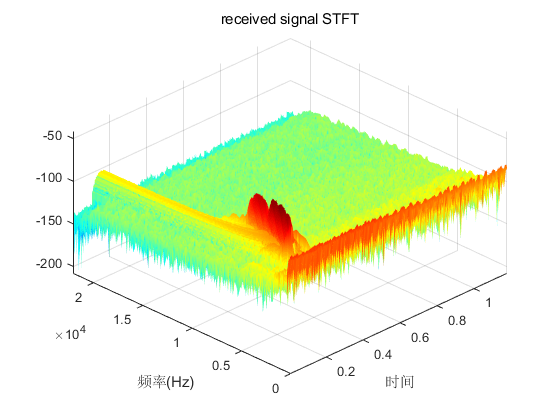



fig = figure;
[y,f,t,p] = spectrogram(recordY, 256, 250, 256, samplingRate);
surf(t,f,10*log10(abs(p)),'EdgeColor','none');  
axis xy; axis tight; colormap(jet); 
view(-45,45);
xlabel('时间');
ylabel('频率(Hz)');
title("received signal STFT");

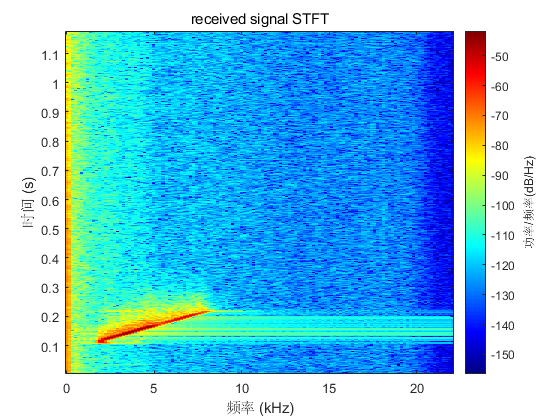

spectrogram(recordY, 256, 250, 256, samplingRate);
title("received signal STFT");
saveas(fig,strcat(outputFigPath, "received_signal_STFT.png"));

## 继续是频谱图

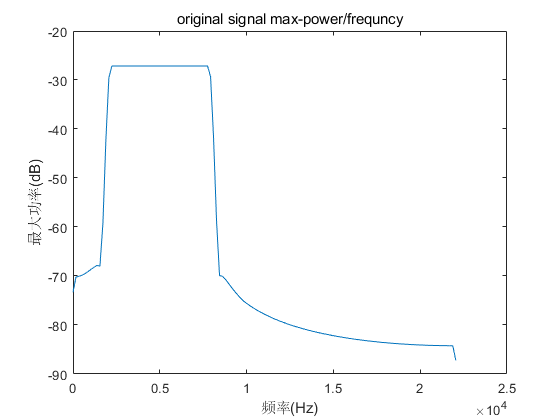

[s,f,t,p] = spectrogram(originY, 256, 250, 256, samplingRate);
max(10*log10(p),[],2);
fig = figure;
plot(f, max(10*log10(p),[],2))
title("original signal max-power/frequncy");
ylabel('最大功率(dB)');
xlabel('频率(Hz)');
saveas(fig,strcat(outputFigPath, "original_signal_power_frequncy.png"));

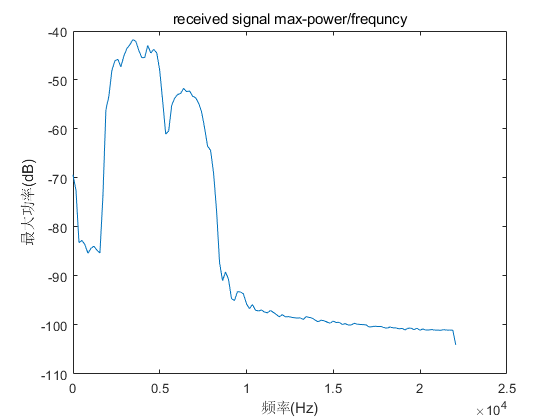


[s,f,t,p] = spectrogram(recordY, 256, 250, 256, samplingRate);
max(10*log10(p),[],2);
fig = figure;
plot(f, max(10*log10(p),[],2))
title("received signal max-power/frequncy");
ylabel('最大功率(dB)');
xlabel('频率(Hz)');
saveas(fig,strcat(outputFigPath, "received_signal_power_frequncy.png"));

## 测试函数

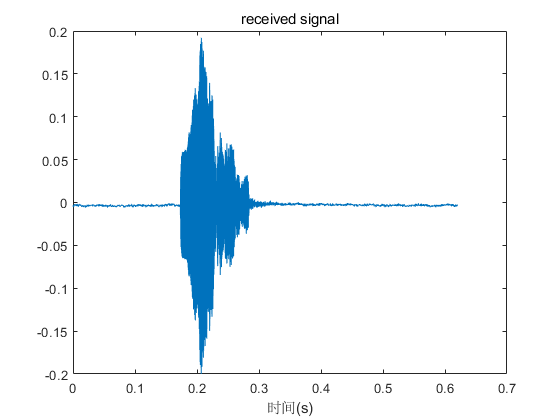

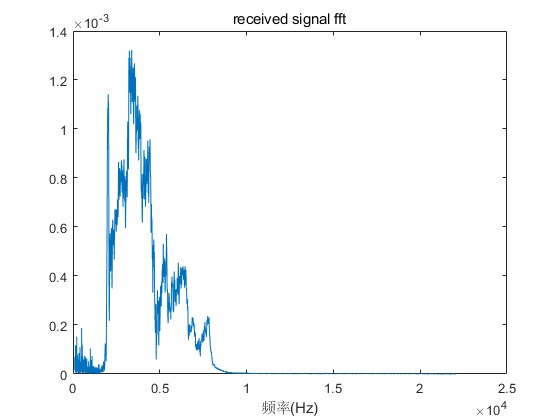

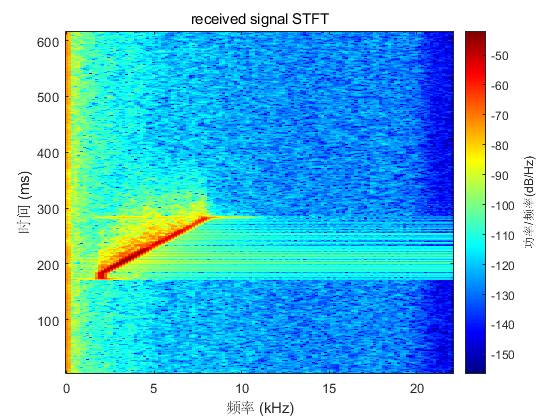

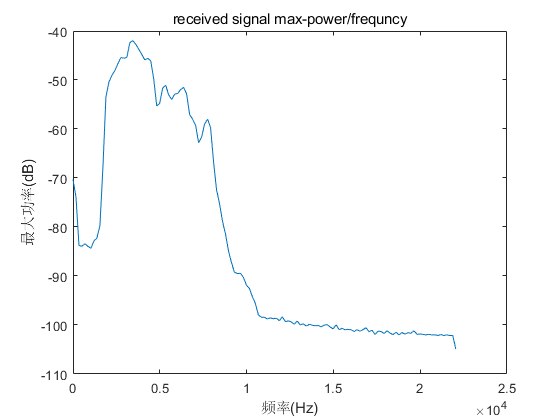

recordAnalysis("D:/WorkSpace/IDEA/beepbeep-server/static/experiment/type2/_signals/pure/1_44k_2k_8k_100_pure.wav", ...
    "D:/WorkSpace/IDEA/beepbeep-server/static/experiment/type2/29/record.wav", ...
    "D:/WorkSpace/IDEA/beepbeep-server/static/experiment/type2/29/")